## Week 7 - Solving Differential Equations

So much of science and engineering comes down to solving ordinary of partial differential equations. These equations seek to model the rates of change of some quantity (either in space or time, or both). Some times, the equation to be solved is very simple, and we can obtain exact 'analytic' solutions. Other times, the equation is more complex and requires computer solution. Numerical methods for solving ODEs and PDEs is a huge topic and you can take an entire quarter class learning about it. I would like to show you a few strategies to get you started...

Let us first consider ordinary differential equations. These come as 'initial value' or 'boundary value' problems. In addition, they can be first, second, etc. 'order' depending upon the highest derivative.

clear all
close all
clc


## Block 1 - First Order Initial Value Problem

A 'first order' equation simply means that the highest derivative we have is $\frac{dy}{dx}$. A second order equation would contain a term like $\frac{d^{2}y}{dx^{2}}$. An 'initial value' problem means that we know the solution of the problem at ONE location, and we are going to figure out the solution everywhere else starting from that initial value. Now, to solve a differential equation numerically, we replace the derivative with a finite difference approximation:


$$\frac{dy}{dx}\approx \frac{y_{n+1}-y_{n}}{\Delta x}$$


Here, the subscript indicates the 'grid point' we are talking about. When we use 'finite difference' solutions, we are no longer going to get a solution at every x value. Instead, we get a solution on a 'grid' of x values. So, $x_{n}$ is the location of our current grid point and $y_{n}$ is the solution at the current grid point. So, in the above equation, our derivative gets replaced by a linear approximation based upon the solution at the current grid poing $y_{n}$ and the next grid point $y_{n+1}.$ 

So, how does this help? Well, assume that we have a differential equation of the form

$\frac{dy}{dx}=f(x,y)$. The right hand side of this is called the derivative function and can be anything. If we substitue in our approximation of the derivative into this equation we get

$y_{n+1}=f_{n}(x,y)\Delta x+y_{n}$. This is remarkable. We can compute the value of our solution at the next (n+1) grid point, based ONLY on known information at the current (n) grid point. Let's demonstrate this with an easy example:

Let us consider the following equation and initial condition.


$$\frac{dy}{dx}-xy^{2}-y=0\qquad y(x=0)=1$$


Thus, our derivative function f is given by


$$f=xy^{2}+y$$


Let us set the 'domain' over which we wish to solve this equation and also choose the 'step size.' And, let us set the initial condition.

xmin=0;
xmax=.8;
dx=.01;
x=[xmin:dx:xmax];
y(1)=1;

So, now we just use a loop to numerical solve the equation.

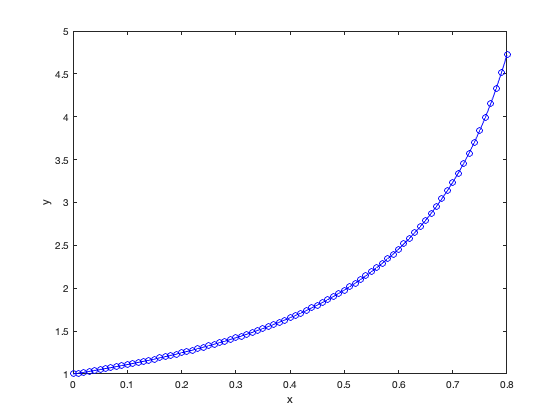

for j=1:length(x)-1
    f=x(j)*y(j)^2+y(j);
    y(j+1)=f*dx+y(j);
end
figure(1)
plot(x,y,'b-o');xlabel('x');ylabel('y');
hold on

A key thing to note about numerical solutions of differential equations. If we make a poor choice for our step size, we can get poor results. Let us illustrate that here with a much larger step size. In the figure below the 'divergence' between the two curves shows the accumulation of what are called truncation errors.

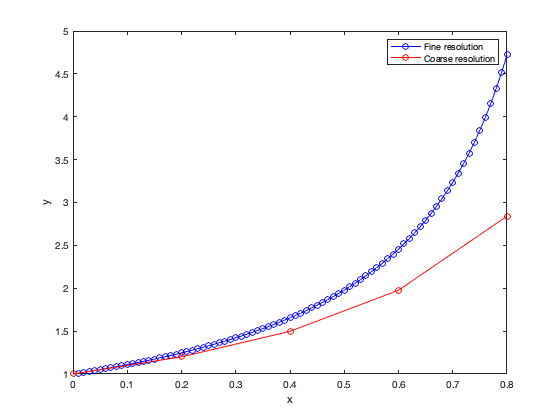

%redo with poor resolution
dx=.2;
clear x y
x=[xmin:dx:xmax];
y(1)=1;
for j=1:length(x)-1
    f=x(j)*y(j)^2+y(j);
    y(j+1)=f*dx+y(j);
end

plot(x,y,'r-o');xlabel('x');ylabel('y');
legend('Fine resolution','Coarse resolution')

## Block 2 - Numerical Instability

In the section above, we saw that if we did not choose dx carefully (make it small enough) we got errors. In this example, I want to illustrate that things can get even worse. For some values of dx, not only will the solution encounter truncation errors, but it can encounter catastrophic instability.

We will look at the equation


$$\frac{dy}{dx}+y=0 \qquad y(0)=1$$


which has the simple analytic solution of 


$$y=e^{-x}$$


I will plot 3 solutions; the exact, a numerical with 'good' resolution and a numerical with 'poor' resolution. Note that for the 'poor' resolution the symbols are diverging, i.e. getting farther and farther away from the correct answer. 

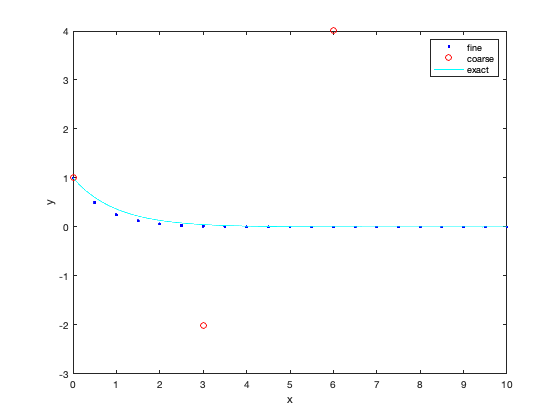

clear all
xmin=0;
xmax=10;
dx=0.5;
x=[xmin:dx:xmax];
y(1)=1;
for j=1:length(x)-1
    f=-y(j);
    y(j+1)=f*dx+y(j);
end
figure(2); hold off
plot(x,y,'b.');xlabel('x');ylabel('y');
hold on

%redo with poor resolution
dx=3;
clear x y
x=[xmin:dx:xmax];
y(1)=1;
for j=1:length(x)-1
    f=-y(j);
    y(j+1)=f*dx+y(j);
end
plot(x,y,'ro');xlabel('x');ylabel('y');

% add exact solution
x=linspace(0,10,1000);
plot(x,exp(-x),'c')
axis([0 10 -3 4]) 

legend('fine','coarse','exact')

## Block 3 - Built in ODE solvers

The above is a very low order solution method, with large potential errors. Higher order solutions (Runge-Kutta) exist and are automated in Matlab. They are much better since the truncation error is less. I will illustrate this with the FIRST equation that we solved.

clear all
close all
xmin=0;
xmax=.9;
y0=1;
f=@(x,y) x*y^2+y;

Note the syntax in the next line. You have to send in to ODE45 the 'function name', the domain range, and a starting value. You do NOT pick a dx.

[x,y]=ode45(f,[xmin xmax],y0);
figure(3); hold off
plot(x,y,'b.')
xlabel('x');ylabel('y');
hold on

Note that the spacing of the dots is not necessarily constant. Matlab clevely figures out where the solution is changing rapidly and will use a smaller dx there. In areas where the solution changes slowly, Matlab will use a larger dx. Now, let us go back and add to this our simple Euler solution.

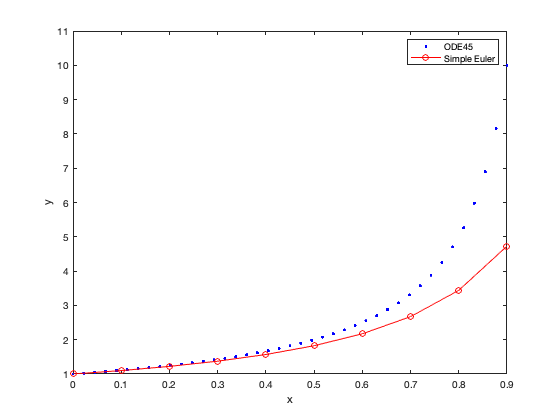

clear all
xmin=0;
xmax=.9;
dx=.1;
x=[xmin:dx:xmax];
y(1)=1;
for j=1:length(x)-1
    f=x(j)*y(j)^2+y(j);
    y(j+1)=f*dx+y(j);
end
plot(x,y,'r-o');legend('ODE45','Simple Euler')


% note: rather than using anonymous / inline functions, you can have an
% external function written into another mfile.

## Block 3 - 'Stiff' ODEs

A 'stiff' ODE is one where the solution may very quite rapidly is some locations, requiring a VERY small step size. ODE45 is good to use in these cases, since it will figure out where to use a very small dx and where it can use a larger dx. Let us look at the equation


$$\frac{dy}{dt}=y-t^{2}\qquad y(0)=2$$


and let us solve it over range $0<t<10$. In the plot below, you will see that the simple Euler approach goes 'off the rails' and blows up, whereas ODE45 is perfectly capable of finding the right solution.

% First, try our basic euler method

clear all
tmin=0; tmax=10; dt=0.25;
t=tmin:dt:tmax;
y(1)=2;
y0=y(1);
for j=1:length(t)-1
    f=y(j)-t(j)^2;
    y(j+1)=y(j)+dt*f;
end
figure(4)
plot(t,y,'b-o')

% now try ode45
f=@(t,y) y-t^2
[t,y]=ode45(f,[tmin tmax],y0);
hold on
plot(t,y,'r.')
legend('simple euler','ode45','location','southwest')

## Block 4 - System of ODEs

What if we have a coupled system of first order ODEs? We can't write that into an anonymous function, so we tackle with a separate file. Here, we will consider the system


$$\frac{dx}{dt}=-\sigma x + \sigma y
$$



$$\frac{dy}{dt}=\rho x - y - xz$$



$$\frac{dz}{dt}=-\beta z + xy$$


This is a system of equations that can be used to model chaotic behavior in a dynamical system. The parameters $(\rho,\sigma,\beta)$ determine the nature of the solution.

clear all
%set parameters
sigma=10;
beta=8/3;
rho=28;
%set initial conditions
x0=-8;
y0=8;
z0=27;
%create vector of parameters
p=[sigma beta rho];
%create vector of initial conditions
X0=[x0 y0 z0];
%define time domain over which to solve the problem
tspan=[0,20];
%solve the system of equations! Note the syntax used to 'pass in' the
%parameters to the function. Also note: the 'job' of the function
%lorenz_dfh (see the .m file included with class notes is to return a vector that contains the 'derivative functions'
%of the three differential equations we are solving. Please view the code
%in the function and make sure you understand this.
[t,x]=ode45(@lorenz_dfh,tspan,X0,[],p);
figure(5)
plot3(x(:,1),x(:,2),x(:,3))
grid on
xlabel('x');ylabel('y');zlabel('z')

figure(6)
subplot(3,1,1)
plot(t,x(:,1));ylabel('x');
subplot(3,1,2)
plot(t,x(:,2));ylabel('y');
subplot(3,1,3)
plot(t,x(:,3));xlabel('t');ylabel('z')

## Block 5 - Higher Order ODEs

Ok, so what do we do if we have 2nd-order (or higher) ODEs? Let's consider the example


$$\frac{d^{2}y}{dx^{2}}+8\frac{dy}{dx}+2y=\cos(x)\qquad y(0)=0\qquad \frac{dy}{dx}=1$$


Since it is a second order equation, we need two conditions to solve it, and two are given; on on the value of the function y and one on its derivative. We will solve this by reducing this one second order equation to a system of two first order equations. How? By defining new variables.

Let us define


$$y_{1}=y\qquad y_{2}=\frac{dy}{dx}=\frac{dy_{1}}{dx}$$


So, our first equation to solve is:


$$\frac{dy_{1}}{dx}=y_{2}$$


and our second equation to solve comes from the given equation above


$$\frac{d^{2}y}{dx^{2}}+8\frac{dy}{dx}+2y=\cos(x)$$



$$\frac{d}{dx}\biggl(\frac{dy}{dx}\biggr)+8\frac{dy}{dx}+2y=\cos(x)$$



$$\frac{dy_{2}}{dx}+8y_{2}+2y_{1}=\cos(x)$$



$$\frac{dy_{2}}{dx}=-8y_{2}-2y_{1}+\cos(x)$$


There you go! Our system of equations is now


$$\frac{dy_{1}}{dx}=y_{2} \qquad y_{1}(0)=0$$



$$\frac{dy_{2}}{dx}=-8y_{2}-2y_{1}+\cos(x) \qquad y_{2}(0)=1$$


clear all 
close all
%set the initial conditions
Y10=0;
Y20=1;
%set the domain rainge
xspan=[0,10];
%create vector of initial conditions
Y0=[Y10 Y20];
%solve it! Note that I am using a function that I wrote and that is
%supplied with the notes for this week.
[x,y]=ode45(@secondorder,xspan,Y0);
figure(1)
plot(x,y)
grid on
xlabel('x');ylabel('y');legend('y1','y2')
%remember that y1=y. We defined that. So, our 'final answer' is y1.

## Block 6 - Boundary Value Problems

Everything we have done so fas has been an initial value problem. In the case of the coupled equations, we had conditions on each variable at the same location, and we integrated the solution away from that point to get the solution everywhere else. Let us now turn our attention to the case of boundary value problems. A boundary value problem is one where you have a condition on the solution at multple points (two boundaries of the domain) and you to solve for the solution everywhere else. As a point of context, think of the classic projectile problem, where we 'launch' a projectile at a given angle and speed. The governing equations for the position (x [horizontal], y [vertical]) are (if we assume no air resistance)


$$\frac{d^{2}x}{dt^{2}}=0$$



$$\frac{d^{2}y}{dt^{2}}=-g$$
 

where g is the gravitational constant. So, we use the trick from above to reduce these two 2nd order equations to a system of 4 1st order equations. We do this by introducing new variables:


$$x_{1}=x\qquad x_{2}=\frac{dx}{dt}=\frac{dx_{1}}{dt$$


And the given equation above becomes:


$$\frac{d^{2}x}{dt^{2}}=0$$



$$\frac{d}{dt}\biggl(\frac{dx}{dt}\biggr)=0$$



$$\frac{dx_{2}}{dt}=0$$


Thus our first two equations are summarized as


$$\frac{dx_{1}}{dt}=x_{2}\qquad\frac{dx_{2}}{dt}=0$$


I will leave it to you to work out the two equations we get from the y equation up above. So, we have 4 equations, and we therefore need 4 conditions. In the 'initial value problem' version of this problem, we specific the initial velocity (angle and speed) andthe initial position of the projectile. That is a total of 4 conditions, all known at $t=0$. So, we then integrate away and we compute the trajectory and the impact point.

In the boundary value problem, it is more complicated. We will typically know the initial position (x and y). So, two conditions are know. AND, we will usually prescribe the impact location, i.e. 


$$x(t=t_{f})=R\qquad y(t=t_{f})=0$$


So, at some 'final time' we want the projectile to hit a location (on the ground, so y = 0) some distance (or range) R away! That is two more conditions, that's great. We have four! But, the methods that we have been talking about so far can't be used in this way. 

So, what do we do? We GUESS initial values for speed and angle, compute the trajectory, see if we hit the target. If not, we try other values for the missing initial conditions. Essentially, this turns into a parameter estimation problem just like one of our previous classes. So, we can write code to find the best values for the missing initial conditions. This is called the 'shooting' method for solving boundary value problems.

I would like to illustrate this with a different example. The equation is


$$\frac{d^{2}y}{dx^{2}}+(-5-10x)\frac{dy}{dx}-10y=0\qquad y(0)=1\qquad y(1)=0$$


So, let us turn this 2nd order ODE into a system of two first order ODEs as follows


$$y_{1}=y\qquad y_{2}=\frac{dy}{dx}=\frac{dy_{1}}{dx}$$


So, our first ODE is given by


$$\frac{dy_{1}}{dx}=y_{2}$$


And our second ODE comes from the given equation


$$\frac{d^{2}y}{dx^{2}}+(-5-10x)\frac{dy}{dx}-10y=0$$



$$\frac{d}{dx}\biggl(\frac{dy}{dx}\biggr)+(-5-10x)\frac{dy}{dx}-10y=0$$



$$\frac{d}{dx}(y_{2})+(-5-10x)y_{2}-10y_{1}=0$$



$$\frac{dy_{2}}{dx}=(10x+5)y_{2}+10y_{1}$$


The boundary conditions become $y_{1}(0)=1$and $y_{1}(1)=0$. For us to do this as a 'shooting method' problem, we will have to guess the value of $y_{2}(0)$, solve the problem and then check on the value of $y_{1}(1)$. This is tedious to do manually (trial and error) so we will automate it.

clear all
y1_init=1;
y1_final=0;
y2_init_guess=[-10 10]; %range of values
y2_init=fminbnd('shoot_test',y2_init_guess(1),y2_init_guess(2),[],y1_init,y1_final);
y2_init %print to screen

You need to examine the code VERY carefully here. The ONLY thing that shoot_test.m does is that it returns the absolute value of the computed y1(1) and the GIVEN boundary condition of y1(1). Inside shoot_test.m, that function in turn calls shoot_test_2.m. The ONLY function of shoot_test_2 is to carry out the numerical integration of the solution. So, shoot_test_2 does the numerical integration, and shoot_test determines the error, and fminbnd is trying a bunch of initial conditions for y2 in order to minimize that error.

Below, I take the 'best' value of y2_init, and just as a test, I call shoot_test_2 with this initial condition and I check on the answer to ensure that y1(1)=0.

[X,Y]=ode45('shoot_test_2',[0 1],[y1_init y2_init]);
figure(1)
hold off
plot(X,Y(:,1));
hold
plot(X,Y(:,2),'r');
axis([0 1 0 max(Y(:,1))])
legend('y ( or y1)','dy/dx ( or y2)','location','southwest')